## **Driver test program to check Clothoids library**

**Test Intersection**

close all;

x0     = 0;
y0     = 0;
theta0 = pi*0.7;
k0     = -0.1;
dk     = 0.05;
L      = 100;
C1     = ClothoidCurve( x0, y0, theta0, k0, dk, L );

x0     = -13;
y0     = 0.3;
theta0 = pi/4;
k0     = 0.1;
dk     = -0.05;
L      = 110;
C2     = ClothoidCurve( x0, y0, theta0, k0, dk, L );

max_angle = pi/2;
max_size  = 0.5;

npts = 1000;

C1.plot(npts,'Color','red','LineWidth',3);
hold on;
C2.plot(npts,'Color','black','LineWidth',3);

C1.noAABBtree();
%C1.yesAABBtree();

tic
[s1,s2] = C1.intersect( C2 );
toc

Elapsed time is 3.090386 seconds.



size(s1)

ans =    625     1


size(s2)

ans =    625     1


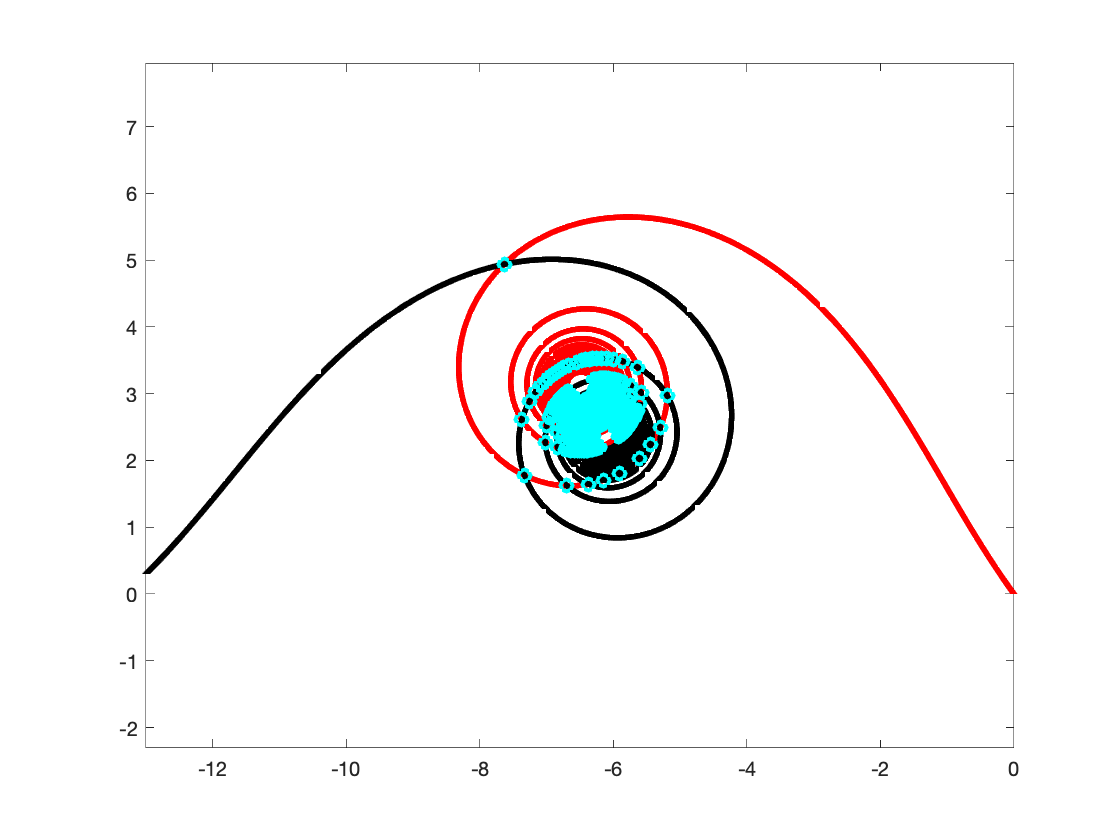


XY1 = C1.eval( s1 );
XY2 = C2.eval( s2 );

plot( XY1(1,:), XY1(2,:), 'ob', 'LineWidth', 2 );
plot( XY2(1,:), XY2(2,:), 'oc', 'LineWidth', 2 );

axis equal;


[P1,P2,P3] = C1.bbTriangles();
fprintf(1,'Triangles of curve C1, %d\n',size(P1,2) );

Triangles of curve C1, 1387




[P1,P2,P3] = C2.bbTriangles();
fprintf(1,'Triangles of curve C2, %d\n',size(P1,2) );

Triangles of curve C2, 1682
